La imagen 1 tiene 2 objetos.
La imagen 2 tiene 2 objetos.
La imagen 3 tiene 2 objetos.
La imagen 4 tiene 2 objetos.
La imagen 5 tiene 2 objetos.
La imagen 6 tiene 2 objetos.
La imagen 7 tiene 2 objetos.
La imagen 8 tiene 2 objetos.
La imagen 9 tiene 2 objetos.
La imagen 10 tiene 2 objetos.
La imagen 11 tiene 3 objetos.
La imagen 12 tiene 3 objetos.
La imagen 13 tiene 3 objetos.
La imagen 14 tiene 3 objetos.
La imagen 15 tiene 3 objetos.
La imagen 16 tiene 3 objetos.
La imagen 17 tiene 3 objetos.
La imagen 18 tiene 3 objetos.
La imagen 19 tiene 3 objetos.
La imagen 20 tiene 3 objetos.
La imagen 21 tiene 3 objetos.
La imagen 22 tiene 4 objetos.
La imagen 23 tiene 4 objetos.
La imagen 24 tiene 4 objetos.
La imagen 25 tiene 4 objetos.
La imagen 26 tiene 4 objetos.
La imagen 27 tiene 4 objetos.
La imagen 28 tiene 4 objetos.
La imagen 29 tiene 4 objetos.
La imagen 30 tiene 4 objetos.
La imagen 31 tiene 4 objetos.
La imagen 32 tiene 4 objetos.
La imagen 33 tiene 5 objetos.
La imagen 34 tiene 

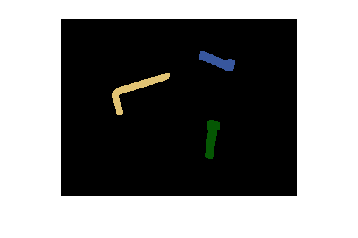

La imagen 12 tiene 3 objetos.
Hasta pronto c:


num_objects = count_objects('C:\Users\Susan\OneDrive\Documentos\MATLAB\VISION\Fotos');

function num_objects = count_objects(folder_path)

    file_list = dir(fullfile(folder_path, '*.bmp')); % Selecciona solo los archivos .bmp
    num_images = numel(file_list); % Obtiene el número de imágenes en la carpeta
    image_array = cell(1, num_images); % Crea un arreglo de celdas para almacenar las imágenes
    num_objects = zeros(1, num_images); % Crea un arreglo para almacenar el número de objetos en cada imagen

    for i = 1:num_images
        file_name = file_list(i).name;
        file_path = fullfile(folder_path, file_name);
        image = imread(file_path);
        gray_image = im2gray(image); % Convierte la imagen a escala de grises
        binary_image1 = im2bw(gray_image); % Binariza la imagen en escala de grises
        min_object_size = 1; % Define el tamaño mínimo del objeto para mantener
        
        binary_image2 = bwareaopen(binary_image1, min_object_size);

        %se = strel('disk',3); % elemento estructurante para las operaciones morfologicas
        %binary_image = imopen(binary_image2, se); % aplica operaciones morfologicas de apertura, erosion seguida de dilatación

        se = strel('disk', 3); % Elemento estructurante para la dilatación
        binary_image = imdilate(binary_image2, se); % Aplica operación de dilatación


        % Etiqueta los objetos en la imagen binaria utilizando el algoritmo Flood-Fill
        labeled_image = zeros(size(binary_image)); % Crea una matriz de etiquetas inicializada en cero
        label = 1; % Inicializa la etiqueta en 1
        for x = 1:size(binary_image, 1)
            for y = 1:size(binary_image, 2)
                if binary_image(x, y) == 1 && labeled_image(x, y) == 0 % Si el píxel es blanco y no ha sido etiquetado
                    labeled_image = flood_fill(x, y, binary_image, labeled_image, label); % Etiqueta el objeto utilizando Flood-Fill
                    label = label + 1; % Incrementa la etiqueta
                end
            end
        end

        num_objects(i) = label - 1; % Almacena el número de objetos en la imagen

        % Genera una paleta de colores aleatorios para etiquetar cada objeto
        colors = rand(num_objects(i), 3);

        % Etiqueta cada objeto con un color diferente
        color_labeled_image = label2rgb(labeled_image, colors, 'k');

        image_array{i} = color_labeled_image; % Almacena la imagen etiquetada en el arreglo

        % Muestra el número de objetos encontrados
        fprintf('La imagen %d tiene %d objetos.\n', i, num_objects(i));
        imshow(color_labeled_image);
        %pause(1)
    end

    montage(image_array, 'Size', [1, 5]);
    bandera =1;
    while bandera == 1
        sn= input('¿Deseas consultar una imagen? ', 's'); %solicita una cadena        
        if strcmpi(sn, 'n')
            disp("Hasta pronto c:")
            bandera=0;
        else
            n_imagen = input("Ingresa el numero de la imagen");            
            mostrar = image_array{n_imagen};
            imshow(mostrar)
            fprintf('La imagen %d tiene %d objetos.\n', n_imagen, num_objects(n_imagen));
        end
    end
    
end
function [labeled_image, updated_label] = flood_fill(x, y, binary_image, labeled_image, label)
    % Etiqueta el píxel actual
    labeled_image(x, y) = label;

    % Define las posibles posiciones de los píxeles adyacentes
    positions = [-1, 0; 0, -1; 0, 1; 1, 0];

    % Recorre las posiciones adyacentes al píxel actual
    for i = 1:size(positions, 1)
        x_new = x + positions(i, 1);
        y_new = y + positions(i, 2);
        % Comprueba si la nueva posición está dentro de los límites de la imagen
        if x_new >= 1 && x_new <= size(binary_image, 1) && y_new >= 1 && y_new <= size(binary_image, 2)
            % Comprueba si el píxel adyacente es blanco y no ha sido etiquetado
            if binary_image(x_new, y_new) == 1 && labeled_image(x_new, y_new) == 0
                % Etiqueta el píxel adyacente y los píxeles adyacentes a este
                [labeled_image, updated_label] = flood_fill(x_new, y_new, binary_image, labeled_image, label);
            end
        end
    end

    % Devuelve la imagen etiquetada y la etiqueta actualizada
    updated_label = label + 1;
end
